# Define the vehicle parameters for the drive cycle sim

## Load AMK Motor Data

load A2370DD_T80C.mat;

## Conversion Factors

k_RPMToRadPerSec = 2*pi/60;
k_radPerSecToRPM = 60/(2*pi);
k_inchesToMeter = 1/39.37;
k_degreesToRad = pi/180;
k_kphToMeterPerSec = 1/3.6;
k_metersPerSecTokph = 3.6;
k_ampHourToCoulombs = 36000;
k_coulombToampHour = 1/3600;
k_joulesTokWH = 1/3600000;

## Vehicle Setup

k_numberOfMotors = 4;

## Driver Parameters

Driver.k_kp = 10;
Driver.k_ki = 1;
Driver.k_kff = 0.05;
Driver.k_kg = 0;
Driver.k_vnom = k_kphToMeterPerSec * 60;
Driver.k_kaw = 0.1;
Driver.k_tauerr = 0.03;

## Pedal Mapping

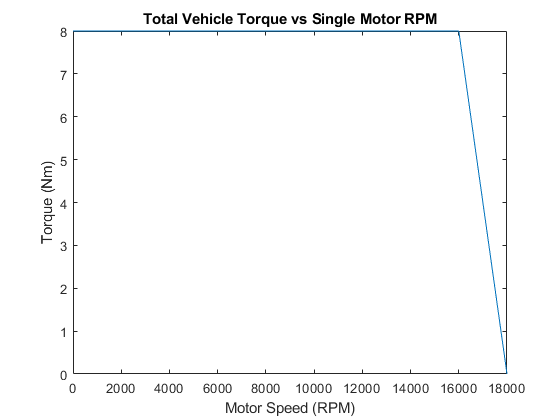

PedalMap.k_motorRPMBreakPoints =    [0,     16000,  18000]; %rpm
%PedalMap.k_maxTorqueLookupTable =   [13.75, 7.50,   0.00] * k_numberOfMotors; %Nm
PedalMap.k_maxTorqueLookupTable =   [2, 2,   0.00] * k_numberOfMotors; %Nm
plot(PedalMap.k_motorRPMBreakPoints, PedalMap.k_maxTorqueLookupTable);
title('Total Vehicle Torque vs Single Motor RPM');
xlabel('Motor Speed (RPM)');
ylabel('Torque (Nm)');

## Brakes

Brakes.k_maxBrakeTorque = 2400; %Nm

## Regen

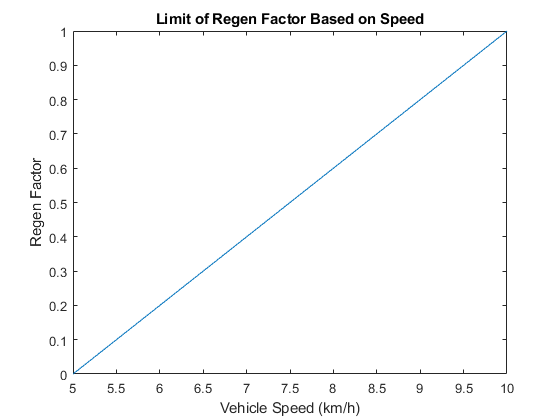

Regen.k_regenEnable =   0;
Regen.k_regenFactorSpeedBreakPoints = [5,10]; %km/h
Regen.k_regenFactorSpeedLookupTable = [0,1];
plot(Regen.k_regenFactorSpeedBreakPoints, Regen.k_regenFactorSpeedLookupTable);
title('Limit of Regen Factor Based on Speed');
xlabel('Vehicle Speed (km/h)');
ylabel('Regen Factor');

## Tires

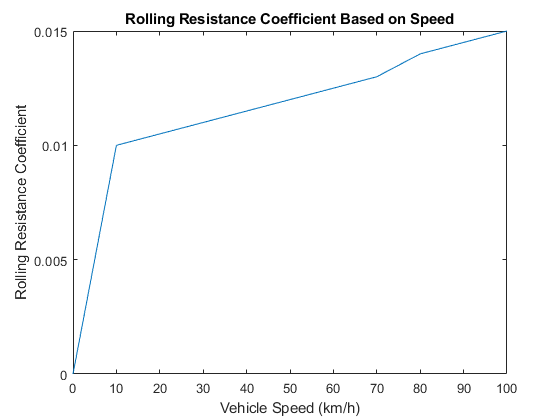

Tire.k_radius = k_inchesToMeter * 10; %m
Tire.k_rollingRadiusSpeedBreakPoints = [
0,  10,     20,     30,     40,     50,     60,     70,     80,     90,     100]; %km/h
Tire.k_rollingRadiusLookup = [
0,  0.01,   0.0105, 0.011,  0.0115, 0.0120, 0.0125, 0.0130, 0.0140, 0.0145, 0.0150];
plot(Tire.k_rollingRadiusSpeedBreakPoints, Tire.k_rollingRadiusLookup);
title('Rolling Resistance Coefficient Based on Speed');
xlabel('Vehicle Speed (km/h)');
ylabel('Rolling Resistance Coefficient');

## Motors

% rows correspond to speed, columns correspond to torque
Motor.k_voltageLineDCLookpupTable = Voltage_Line_RMS*sqrt(2);
Motor.k_voltageLineDCTorqueBreakPoints = k_numberOfMotors * Electromagnetic_Torque(1,:)';


### Efficiency Table

The efficiency table includes losses for both the inverter and the motor.

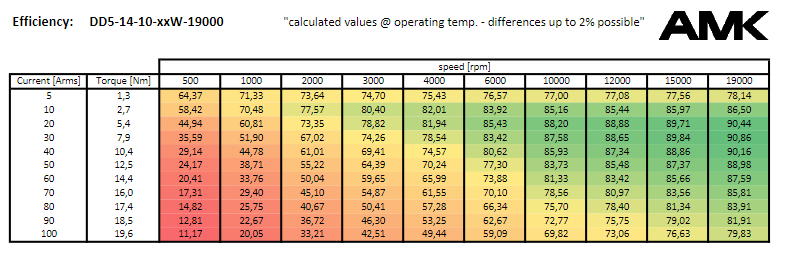

Variables for a 2D lookup table of the motor efficiency plot. For low speed operation (e.g. below 500 rpm), an efficiency of 0% is used. 

Note: The motor will never be travelling less than 500 rpm.

Motor.k_efficiencyTorqueBreakPoints = k_numberOfMotors * [
0,  1.3,    2.7,    5.4,    7.9,    10.4,   12.5,   14.4,   16.0,   17.4,   18.5,   19.6];  %Nm

Motor.k_efficiencyMotorSpeedBreakPoints = k_RPMToRadPerSec * [
0,  500,    1000,   2000,   3000,   4000,   6000,   10000,  12000,  15000,  19000]; %rpm

[MotorSpeedMesh, TorqueMesh] = meshgrid(Motor.k_efficiencyMotorSpeedBreakPoints, Motor.k_efficiencyTorqueBreakPoints);


Rows correspond to different torque values. Columns correspond to different motor rpm values.

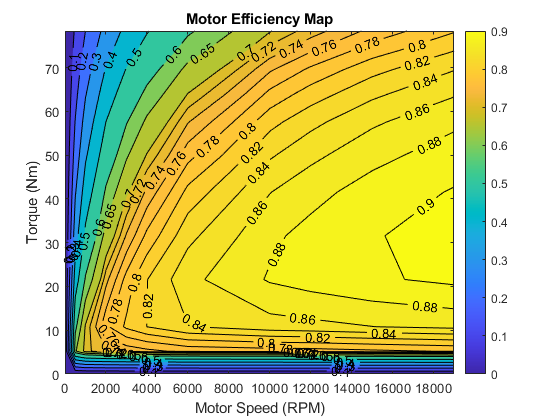

Motor.k_efficiencyLookupTable = 0.01 * [
0.00,   0.00,   0.00,   0.00,   0.00,   0.00,   0.00,   0.00,   0.00,   0.00,   0.00;
0.00,   64.37,  71.33,  73.64,  74.70,	75.43,	76.57,	77.00,  77.08,	77.56,	78.14;
0.00,   58.42,  70.48,	77.57,	80.40,	82.01,	83.92,	85.16,  85.44,	85.97,	86.50;
0.00,   44.94,  60.81,	73.35,	78.82,	81.94,	85.43,	88.20,  88.88,	89.71,	90.44;
0.00,   35.59,  51.90,	67.02,	74.26,	78.54,	83.42,	87.58,	88.65,	89.84,	90.86;
0.00,   29.14,  44.78,	61.01,	69.41,	74.57,	80.62,	85.93,	87.34,	88.86,	90.16;
0.00,   24.17,  38.71,	55.22,	64.39,	70.24,	77.30,	83.73,	85.48,	87.37,	88.98;
0.00,   20.41,  33.76,	50.04,	59.65,	65.99,	73.88,	81.33,	83.42,	85.66,	87.59;
0.00,   17.31,  29.40,	45.10,	54.87,	61.55,	70.10,	78.56,	80.97,	83.56,	85.81;
0.00,   14.82,  25.75,  40.67,	50.41,	57.28,	66.34,	75.70,	78.40,  81.34,	83.91;
0.00,   12.81,  22.67,	36.72,	46.30,	53.25,	62.67,	72.77,	75.75,  79.02,	81.91;
0.00,   11.17,  20.05,	33.21,	42.51,	49.44,	59.09,	69.82,	73.06,  76.63,	79.83];

contourf(k_radPerSecToRPM .* MotorSpeedMesh,TorqueMesh, Motor.k_efficiencyLookupTable, ...
    [0, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.65, linspace(0.7,0.9,11)],'ShowText','on')
colorbar
title('Motor Efficiency Map')
xlabel('Motor Speed (RPM)')
ylabel('Torque (Nm)')


% LossPower = (1/eff - 1)*MechPower
Motor.k_powerLossLookupTable = (1./Motor.k_efficiencyLookupTable - 1).*(TorqueMesh.*MotorSpeedMesh); %W
% Replace the NaN entries caused by the division by zero from the efficiency table
Motor.k_powerLossLookupTable(isnan(Motor.k_powerLossLookupTable)) = 0;

Motor.k_totalDischargeMotorPowerLookupTable = (TorqueMesh.*MotorSpeedMesh + Motor.k_powerLossLookupTable); %W
Motor.k_totalChargeMotorPowerLookupTable = (TorqueMesh.*MotorSpeedMesh - Motor.k_powerLossLookupTable); %W
% Set total charge motor power to 0 where the loss is greater than the regen power
Motor.k_totalChargeMotorPowerLookupTable(Motor.k_totalChargeMotorPowerLookupTable <= 0) = 0;

## Gearbox

Gearbox.k_gearRatio = 13.1;
Gearbox.k_efficiency = 0.95;

## Accumulator

### Cell Parameters

Accumulator.k_cellCapacity = 3.12; %Ah
Accumulator.k_cellCapacityCoulombs = Accumulator.k_cellCapacity; %Ah
Accumulator.k_cellResistance = 0.001 * 18; % ohm

Accumulator.k_nominalCellVoltage = 3.6; %V
Accumulator.k_maxCellVoltage = 4.2; %V
Accumulator.k_minCellVoltage = 2.5; %V

Accumulator.k_maxCellDischargeCurrent = 20; %A
Accumulator.k_maxCellChargeCurrent = 3; %A

Accumulator.k_cellMass = 0.001 * 46.6; % kg

The open circuit voltage curve is based on the following discharge load curve:

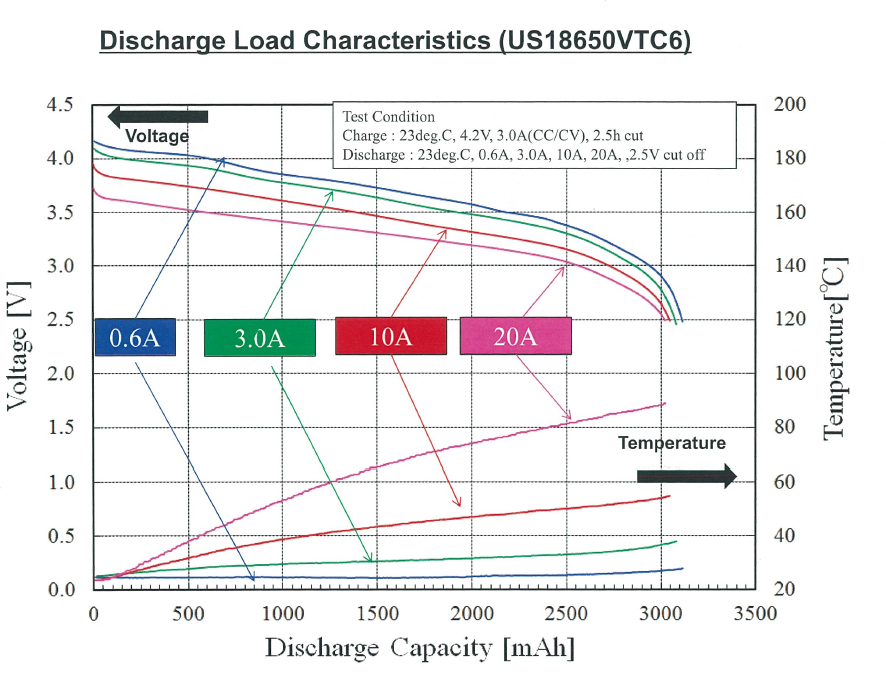

The open-circuit voltage for the cell is obtained by approximating a curve above the 0.6A discharge current curve.

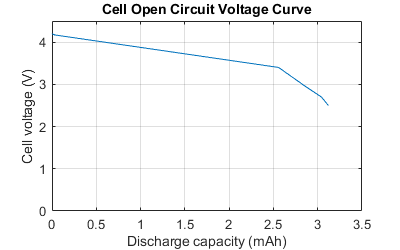

Accumulator.k_cellSOCBreakPoints = [0, 0.025, 0.085, 0.18, 0.99, 1];
Accumulator.k_cellOpenVoltageLookupTable = [Accumulator.k_minCellVoltage, 2.7, 2.96, 3.4, 4.17, Accumulator.k_maxCellVoltage];
plot((1-Accumulator.k_cellSOCBreakPoints)*Accumulator.k_cellCapacity, Accumulator.k_cellOpenVoltageLookupTable);
title('Cell Open Circuit Voltage Curve');
xlabel('Discharge capacity (mAh)');
ylabel('Cell voltage (V)');
ylim([0,4.5])
set(gcf,'position',[0,0,400,250]);
grid on

### Accumulator Pack Configuration

Accumulator.k_numOfParallelCells = 5;
Accumulator.k_numOfSeriesCells = 126;

### Accumulator Pack Specs

Accumulator.k_totalNumOfCells = Accumulator.k_numOfParallelCells * Accumulator.k_numOfSeriesCells;
Accumulator.k_packMass = Accumulator.k_cellMass * Accumulator.k_totalNumOfCells;

Accumulator.k_nominalPackVoltage = Accumulator.k_nominalCellVoltage * Accumulator.k_numOfSeriesCells; %V
Accumulator.k_maxPackVoltage = Accumulator.k_maxCellVoltage * Accumulator.k_numOfSeriesCells; %V
Accumulator.k_minPackVoltage = Accumulator.k_minCellVoltage * Accumulator.k_numOfSeriesCells; %V

Accumulator.k_packCapacity = Accumulator.k_cellCapacity * Accumulator.k_numOfParallelCells; %Ah
Accumulator.k_packCapacityKWhour = Accumulator.k_packCapacity * Accumulator.k_nominalPackVoltage / 1000; %kWh

Accumulator.k_packResistance = (Accumulator.k_cellResistance / Accumulator.k_numOfParallelCells) * Accumulator.k_numOfSeriesCells;
Accumulator.k_maxPackDischargeCurrent = Accumulator.k_maxCellDischargeCurrent * Accumulator.k_numOfParallelCells;
Accumulator.k_maxPackChargeCurrent = Accumulator.k_maxCellChargeCurrent * Accumulator.k_numOfParallelCells;


Accumulator specs based on the cell configurations:

fprintf('The total mass of the cells in the pack is: %f kg', Accumulator.k_packMass);

The total mass of the cells in the pack is: 29.358000 kg

fprintf('The pack capacity is: %f Ah, %f kWh', Accumulator.k_packCapacity, Accumulator.k_packCapacityKWhour);

The pack capacity is: 15.600000 Ah, 7.076160 kWh

fprintf('The pack nominal, max, and minimum voltages are: %f V, %f V, %f V respectively', ...
    Accumulator.k_nominalPackVoltage, Accumulator.k_maxPackVoltage, Accumulator.k_minPackVoltage);

The pack nominal, max, and minimum voltages are: 453.600000 V, 529.200000 V, 315.000000 V respectively

fprintf('The pack max discharge and charge currents are: %f A, %f A respectively', Accumulator.k_maxPackDischargeCurrent, Accumulator.k_maxPackChargeCurrent);

The pack max discharge and charge currents are: 100.000000 A, 15.000000 A respectively

### Charge Limit Curve

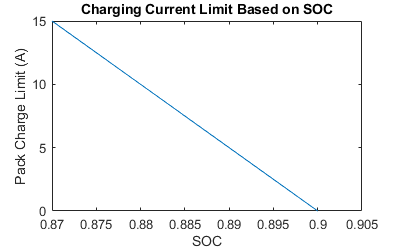

Accumulator.k_chargeLimitSOCBreakPoints = [0.87,0.9];
Accumulator.k_chargeLimitLookuptable = [Accumulator.k_maxPackChargeCurrent, 0]; %A
plot(Accumulator.k_chargeLimitSOCBreakPoints, Accumulator.k_chargeLimitLookuptable);
title('Charging Current Limit Based on SOC');
xlabel('SOC');
ylabel('Pack Charge Limit (A)');

### Initial Conditons

Accumulator.k_initialCellCapacity = Accumulator.k_cellCapacity *1;
Accumulator.k_initialPackVoltage = Accumulator.k_maxPackVoltage;

## Vehicle Parameters

SimVehicle.k_massWithoutAccumulator = 185 + 62; %kg
SimVehicle.k_totalMass = Accumulator.k_packMass + SimVehicle.k_massWithoutAccumulator; % kg
SimVehicle.k_heightOfCenterOfMass = 0.254; %m
SimVehicle.k_distanceCOMtoFrontAxle = 0.7733; %m
SimVehicle.k_distanceCOMtoRearAxle = 0.7517; %m
SimVehicle.k_frontArea = 1.8; %m^2
SimVehicle.k_dragCoefficient = 0.32;
SimVehicle.k_liftCoefficent = 0.1;
SimVehicle.k_maxElectricalPower = 80000; %kW
